# Sistemas de Visión Artificial

# **Práctica 2. Técnicas Básicas de Procesamiento de Imágenes**

**Autor(es): Patricia Cuesta Ruiz y Laura Mambrilla Moreno**

**Fecha:**

El objetivo principal de esta práctica es familiarizarse con las **técnicas básicas de procesamiento de imágenes mediante la *****Image Processing Toolbox***** de Matlab**. Para ello se proponen ejercicios sobre operaciones geométricas, ecualización del histograma, diseño e implementación de filtros y filtrado de imágenes en el dominio del espacio, mediante máscaras de convolución. La mayoría de las técnicas de mejora se aplican a imágenes de intensidad (escala de grises). Para mejorar una imagen RGB, trabajaremos, normalmente, con las matrices de las componentes rojo, verde y azul separadamente.

**La memoria de la práctica se completará en este mismo fichero .mlx**, añadiendo el nombre del autor/autores del grupo, fecha, e insertando el código y los comentarios pertinentes en cada apartado. Las distintas partes serán secciones independientes (deberá insertar "section break" entre ellas), y se visualizarán los resultados conjuntamente con subplot cuando sea conveniente. 

La **calificación **se basará en la corrección del código y de los comentarios (la explicación del código, justificación de los resultados y conclusiones sobre el funcionamiento de cada algoritmo, comparación entre distintos resultados, etc). Por esta razón es imprescindible añadir todas las justificaciones, comparaciones, etc. que se solicitan en el enunciado.

Se valorará positivamente la **ampliación** con las explicaciones que considere oportunas, pruebas adicionales (modificando parámetros, utilizando otras imágenes que resalten algún efecto del procesamiento, etc.), descripción de problemas surgidos en la ejecución de la práctica y solución proporcionada, etc. 

La **entrega **se realizará en el Aula Virtual de la asignatura: Contenidos --> Entregables --> Práctica 2.

clc;
clear all;
close all;

Implemente el siguiente código, visualice los resultados obtenidos y justifíquelos:

1.	Utilice *imageinfo *para averiguar el formato (RGB, mapa de colores indexado, etc.) de una imagen en color (‘canoe.tif’, 'peppers.png',…) y ábrala utilizando las variables adecuadas (J, X, map, etc...).

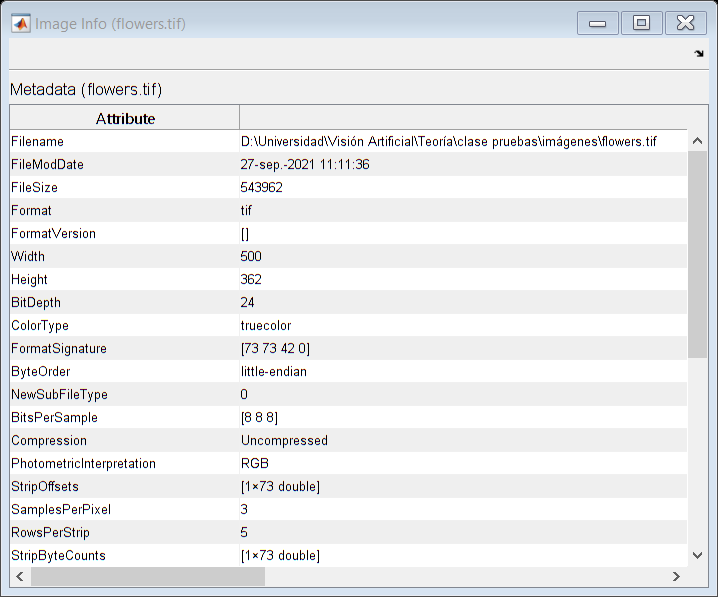

imageinfo('flowers.tif'); % comprobamos la información de la imagen

ini_I = imread('flowers.tif'); % leemos la imagen y la guardamos en una variable

2.	Visualice la imagen que acaba de leer.

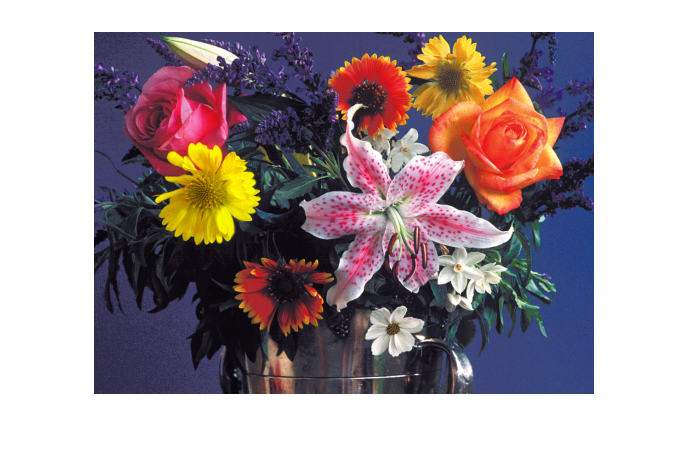

imshow(ini_I); % mostramos la imagen

3.	Convierta la imagen anterior en una imagen en escala de grises y almacénela en un array llamado I. Indique el rango de valores en los que se cuantifica la luminancia (niveles de gris mínimo y máximo) de la imagen resultante.

I = rgb2gray(ini_I);
% imshow(I);
max_I = max(I(:)) 

max_I = uint8
255

min_I = min(I(:))

min_I = uint8
8

4.	Averigüe las dimensiones de nuestra imagen I (filas x columnas).

size_I = size(I);
rows_I = size_I(1) % guardamos el primer valor del array size_I, que corresponde con las filas de I

rows_I = 362

columns_I = size_I(2) % guardamos el segundo valor del array size_I, que corresponde con las columnas de I

columns_I = 500

5.	Muestre el histograma de la imagen I.

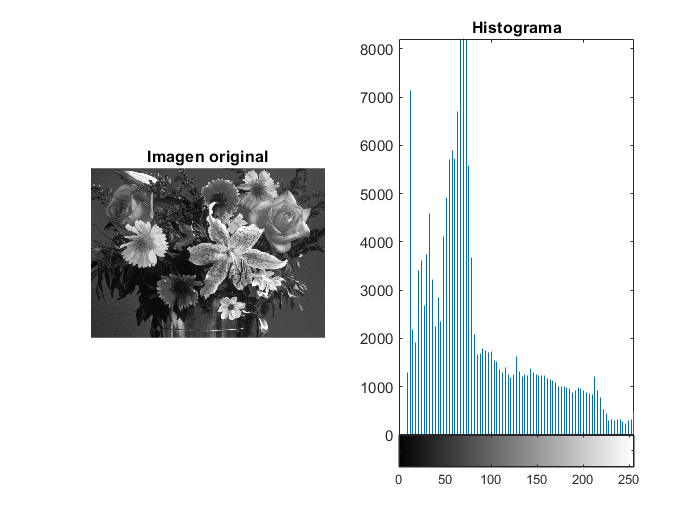

figure
subplot(1,2,1), imshow(I); title('Imagen original');
subplot(1,2,2), imhist(I, 85); title('Histograma');

6.	Modifique el brillo y el contraste de la imagen I y visualice las imágenes resultantes y sus histogramas.

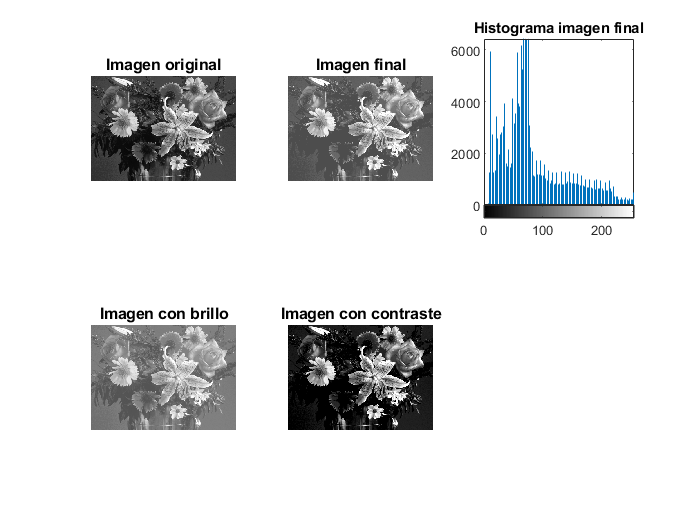

I_double = im2double(I);  % pasamos la imagen I a tipo double
% imadjust(imagen, contraste, brillo)
I_c = imadjust(I, [0.2 0.9], []); % modificamos el contraste
I_b = imadjust(I, [], [0.3 1]); % modificamos el brillo
I_ad = imadjust(I, [0.2 0.9], [0.3 1]); % guardamos la imagen final con el contraste y brillo modificados
figure;
subplot(2,3,1), imshow(I); title('Imagen original');
subplot(2,3,2), imshow(I_ad); title('Imagen final');
subplot(2,3,3); imhist(I, 110); title('Histograma imagen final');
subplot(2,3,4); imshow(I_b); title('Imagen con brillo');
subplot(2,3,5); imshow(I_c); title('Imagen con contraste');

7.	Realice una binarización de la imagen I con un umbral cuyo valor sea aproximadamente la mitad de su rango de grises y visualice el resultado.

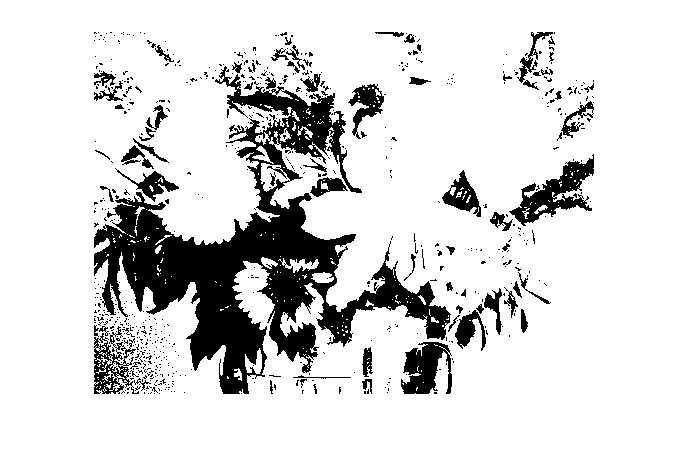

figure;
I_bw = im2bw(I, 0.2);
imshow(I_bw);

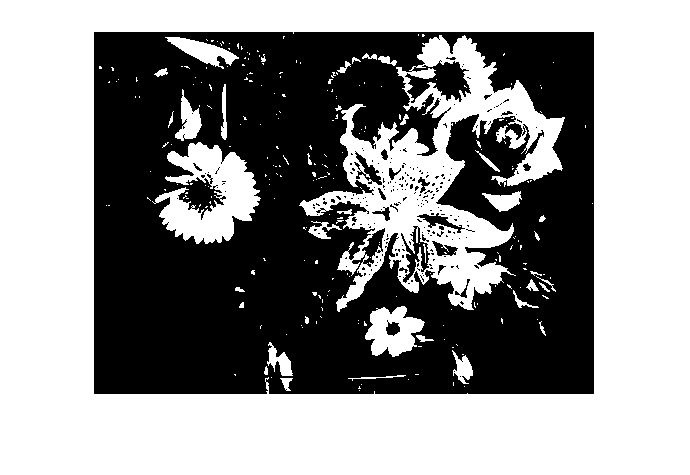

I_bw = im2bw(I, 0.5); % hemos usado el valor 0.5
figure;
imshow(I_bw);

8.	Obtenga el negativo de la imagen I obtenida en el punto 3.

9.	Obtenga y muestre tres versiones ruidosas de la imagen I: 

    (a) con ruido de distribución uniforme ‘speckle’, 

    (b) con ruido de tipo ‘sal y pimienta’ de densidad de ruido 5%, 

    (c) con ruido de tipo gaussiano de media cero y varianza 0.01.

10.	Partiendo de la imagen contaminada con ruido gaussiano anterior, fíltrela utilizando la media del entorno de vecindad, primero con un entorno de vecindad de 3x3 y luego con uno de 5x5, comparando los resultados obtenidos. Justifique sus conclusiones.

11.	Lea la imagen venas.tif y rótela un ángulo de 50 grados (por ejemplo), utilizando los métodos de interpolación nearest y bicubic (parámetros de la función imrotate). Aumente las imágenes lo suficiente para ver las diferencias entre ambos resultados y compárelos.

12.	A partir de la imagen original blood1.tif, obtenga 16 imágenes diferentes con ruido gaussiano de media cero y varianza 0.05. Utilizando la función *imwrite*, guárdelas en ficheros con sus respectivos nombres (ruidosa1.bmp, …, ruidosa16.bmp).

13.	Realice pruebas de filtrado de ruido usando la técnica de promediado de imágenes sobre las imágenes creadas en el punto anterior. Para ello, promedie en primer lugar con 4 imágenes ruidosas, luego con 8 y, finalmente, con las 16. Compare visualmente los resultados y coméntelos.

14.	Utilizando la imagen P2gris.jpg, compuesta únicamente por un fondo grisáceo de luminancia intermedia, complete los siguientes pasos:

- cargue la imagen, conviértala a escala de grises y muestre su histograma,

- contamine con ruido speckle la imagen de grises y almacene el resultado en otro fichero de imagen,

- muestre y observe el histograma de la imagen ruidosa y confirme que el ruido tiene una distribución uniforme,

- consulte la ayuda del comando imnoise, para ver cómo se puede cambiar la varianza del ruido, contamine la imagen original con ruido speckle con diferentes varianzas, muestre y observe qué ocurre con los histogramas de las distintas imágenes ruidosas generadas.

15.	Busque una imagen oscura y con poco contraste, o créela a partir de una fotografía (multiplicando por 0.1 o 0.2 sus niveles de gris). A continuación, visualice dicha imagen y su histograma. Finalmente, aplique el logaritmo a dicha imagen, calculando previamente el valor óptimo de K, para asegurar que el nivel máximo de gris a la salida sea el máximo posible. Visualice la imagen resultante y observe la mejora obtenida. Pruebe utilizando valores de K diferentes al calculado.

16.	Cargue la imagen bazo.bmp y muestre su histograma. Compruebe que se trata de una imagen con poco contraste. Convierta la imagen a escala de grises y luego ecualice su histograma uniformemente. Visualice la imagen resultante y su histograma y comente las diferencias con la imagen original.

17.	Disminuya el brillo de la imagen bazo.bmp hasta que el nivel de gris más bajo sea 0 y realice sobre esa imagen una corrección gamma. Pruebe con distintos valores de gamma y analice el efecto de cada uno sobre la imagen de salida.

18.	Efectúe las siguientes operaciones, relacionadas con la mejora de imágenes: 

        18.1.	Cargue y visualice la imagen ‘pout.tif’.

        18.2.	Compruebe los principales parámetros de la imagen con el comando *imfinfo*.

        18.3.	Muestre el histograma de la misma.

        18.4.	Ecualice el histograma y muestre la imagen y el histograma después de la ecualización. 

        18.5.	Almacene la imagen ecualizada en un fichero jpeg utilizando el comando imwrite.

        18.6.	Sobre la imagen original: Optimice el contraste al máximo, y muestre el histograma de la imagen de salida y su FFT.

        18.7.	Añada ruido gaussiano, muestre el histograma de la imagen con ruido, obtenga su FFT y muéstrela.

        18.8.	Aplique los siguientes filtros a la imagen con ruido y compare las imágenes de salida:

-    un filtro Wiener en el dominio del espacio,

-    un filtro paso bajo en el dominio del espacio,

-    un filtro paso bajo en el dominio de la frecuencia, y

-    un filtro gaussiano. Genérelo con fspecial y pruebe con diferentes valores de los parámetros.